# Molico (2006) Replication

## Calibration

clear 

mupper=500 %highest value if money holdings on the grid

mupper = 500

N=1000 %number of agents for simulating distribution

N = 1000

iterations=10 %maximum number of iterations for the value function iteration    

iterations = 10

stopping_parameter=0 %the smaller, the more does it iteration take to converge

stopping_parameter = 0

x=0.1

x = 0.1000

alpha=1

alpha = 1

theta=1

theta = 1

beta=0.99 %discount factor

beta = 0.9900

M=100 %Money supply

M = 100

r=1/beta-1 %real interest rate

r = 0.0101

## Define grid

% sets up a grid where points are located around 50-100 since under the
% most used calibration, many agents were holding money holdings in that
% range
% grids_1=5
% 
% grids_2=7
% grids_3=5
% grids=grids_1+grids_2+grids_3
% 
% m_0=linspace(0,80,grids_1)
% m_1=linspace(90,200, grids_2)
%  m_2=linspace(220,mupper,grids_3);
%  m=[m_0,m_1,m_2]
grids=17

grids = 17

m=linspace(0,mupper, grids)

m =          0   31.2500   62.5000   93.7500  125.0000  156.2500  187.5000  218.7500  250.0000  281.2500  312.5000  343.7500  375.0000  406.2500  437.5000  468.7500  500.0000


## Options



test_interpolation=0 % checks the interpolation method and displays the initial guess of the value function

test_interpolation = 0

test_utility=0 % displays the utility and cost function

test_utility = 0

## set up matrixes

 M_track_1=zeros(1,iterations)

M_track_1 =      0     0     0     0     0     0     0     0     0     0


  M_track_2       =zeros(1,iterations)

M_track_2 =      0     0     0     0     0     0     0     0     0     0


Trading_Shock=ones(1,N);
Meeting=ones(1,N);
Meeting_Shock=ones(1,N);
initial_distribution_shock=ones(1,N);
q=ones(grids);
d=ones(grids);
V=zeros(1,grids);
V0=zeros(1,grids);
V_new=zeros(1,grids);
count=zeros(grids+1,N);
count_l=zeros(grids,N);
count_u=zeros(grids,N);
Distribution=ones(1,N);
Distribution_new=ones(1,N);
Distribution_number=ones(1,N);
Meeting_type=zeros(1,N);
cdf=zeros(1,grids);
lamdba_0=zeros(1,grids);
lamdba_track=zeros(grids, iterations)

lamdba_track =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


## Initial Guess

% set an initial guess for the value function
V0=log(1+m)*100  ;


V0 =          0  330.8172  452.0224  505.2754  537.1928  558.7984  574.5192  586.5298  596.0370  603.7679  610.1887  615.6129  620.2597  624.2873  627.8130  630.9258  633.6944


 
% set an initial guess for the pdf distributiuon

for j=1:grids
if m(1,j)>M
lamdba_0(1,j)=1
break
end
end

lamdba_0 =      0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0


lamdba_0 =     0.0070    0.0720    0.0840    0.0900    0.2040    0.2420    0.1800    0.0860    0.0250    0.0090    0.0010         0         0         0         0         0         0



M=lamdba_0*m';

%ISSUE: the guess was choosen such that that the implied money supply is
%equal to M. But then the pdf does not sum to 1. I don't think this is a
%problem since after 


% compute cdf
for i=1:grids-1
    cdf(1,1)=lamdba_0(1,1);
cdf(1,i+1)=cdf(1,i)+lamdba_0(1,1+i);
end


% Draw from the initial guess
% we draw a random shock [0,1] for each individual in N. Depending on the
% initial guess, the cdf will determine the distributiuon. Notice, the
% distribution_number is determined to determine the grid point which can
% then be used to determine the money holding by using the grid m

found=0; %this parameter indicates whether a certain condition in the loop was satisfied
for i=1:N
initial_distribution_shock(1,i)=unifrnd(0,1); 
for l=1:grids 
   if initial_distribution_shock(1,i)<cdf(1,l)
Distribution_number(1,i)=l;
Distribution(1,i)=m(1,Distribution_number(1,i));
found=1;
   end
    
if found==1
found=0;
    break
end
       
end

end
 M_N=sum(Distribution);
 



## Test interpolation: spline, extrapolate


if test_interpolation==1
    n_interp=1000
V_interp=ones(n_interp);
m_interp=linspace(1,mupper,n_interp);
for i=1:n_interp
V_interp=interp1(m,V0,m_interp,'spline',"extrap");
end

%Plot
hold on

plot(m,V0)
plot(m_interp,V_interp)
legend('grids', 'interpolation')

hold off

clear  m_interp n_interp V_interp
end


## Test utility and cost function


if test_utility==1
u=Utility(m)
c=cost_function(m)
s=u-c
figure(1)

hold on
plot(m, u)
plot(m,c)
plot(m,s)
legend('Utility', 'Cost', 'Surplus')
title('Functional Form')
hold off
clear u c s
end

## Iteration

V=V0

V =          0  330.8172  452.0224  505.2754  537.1928  558.7984  574.5192  586.5298  596.0370  603.7679  610.1887  615.6129  620.2597  624.2873  627.8130  630.9258  633.6944


lamdba=lamdba_0

lamdba =     0.0070    0.0720    0.0840    0.0900    0.2040    0.2420    0.1800    0.0860    0.0250    0.0090    0.0010         0         0         0         0         0         0



% We compute the intial terms of trade with the guess
for i=1:grids
    for j=1:grids
        x_0=[0.5, m(1,i)./2]; % we choosen the initial guess according to the money holdings of the buyer
[q(i,j),d(i,j)]=Bargaining(m(1,i),m(1,j),m,V,x_0,mupper);
    end
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu





stop=0

stop = 0

for i=1:iterations

    % We update the value function. Note that the value function is the
    % probability of being a buyer times the expected value of being a
    % buyer (TIOLI). The expected value of being a buyer is the utility
    % from consuming minus the value of money that was spent. Notice, that
    % we need to interpolate V because the solution of the bargaining
    % problem is generally not on the grid
for j=1:grids
%V_new(1,j)=(alpha*x/(r+alpha*x)*(Utility(q(j,:))+interp1(m,V,m(1,j)-d(j,:),'spline', 'extrap')-V(1,j))*lamdba';
V_new(1,j)=((alpha*x)/(r+2*alpha*x))*(Utility(q(j,:))+interp1(m,V,m(1,j)-d(j,:),'spline', 'extrap'))*lamdba'...
    +((alpha*x)/(r+2*alpha*x))*(-cost_function(q(:,j))+interp1(m,V,m(1,j)+d(:,j),'spline', 'extrap'))'*lamdba';
end


%stopping rule: if the updated value function is sufficiently close to the
%previous, the algortithm has converged. If this is the case then stopp 1
%and the algorithm will stopp after all the other stuff was computed
if mean((V_new-V).^2)<stopping_parameter
   
stop=1    
end

V=V_new


% From here on we simulate the matching technology and the resulting
% distribution:

%First, we update the terms of trade since we have a estimate of the value
%function

    for i_1=1:grids
    for j_1=1:grids
        x_0=[0.5, m(1,i_1)./2];
[q(i_1,j_1),d(i_1,j_1)]=Bargaining(m(1,i_1),m(1,j_1),m,V,x_0,mupper);
    end
    end

    k=1


while k<N+1

if k==N
    Distribution_new(1,k)=Distribution(1,k);
    break
end



Trading_Shock(1,k)=unifrnd(0,1);
Meeting_Shock(1,k)=unifrnd(0,1);
% if Meeting_Shock(1,k)<cdf(1,1)
%  Meeting(1,k)=1;
% end
% for l=1:grids-1
% if cdf(1,l)<Meeting_Shock(1,k)&& Meeting_Shock(1,k)<cdf(1,l+1)
%     Meeting(1,k)=l+1;
%    
% 
% end
% end

found=0;
for l=1:grids
   if Meeting_Shock(1,k)<=cdf(1,l)
Meeting(1,k)=l;
found=1;
   end
    
if found==1
found=0;
    break
end
       
end






if Trading_Shock(1,k)<alpha*x
    Distribution_new(1,k)=max(Distribution(1,k)-interp1(m,d(:,Meeting(1,k)),Distribution(1,k),'spline','extrap'),0);
    Distribution_new(1,k+1)=max(Distribution(1,k+1)+interp1(m,d(:,Meeting(1,k)),Distribution(1,k),'spline','extrap'),0);
    Meeting_type(1,k)=1;
   Meeting_type(1,k+1)=2;

    k=k+2;
elseif Trading_Shock(1,k)<2*alpha*x
    Distribution_new(1,k)=max(Distribution(1,k)+interp1(m,d(Meeting(1,k),:),Distribution(1,k),'spline','extrap'),0);
      Distribution_new(1,k+1)=max(Distribution(1,k+1)-interp1(m,d(Meeting(1,k),:),Distribution(1,k),'spline','extrap'),0);
         Meeting_type(1,k)=2;
    Meeting_type(1,k+1)=1;

    
        k=k+2;
else 
    Distribution_new(1,k)=Distribution(1,k);
       Meeting_type(1,k)=0;
 
end
    k=k+1;

end

M_track_2(1,i)=sum(Distribution_new)

 Distribution_new=Distribution_new.*(M_N/M_track_2(1,i))




count(1,:)=Distribution_new<=m(1,1);
lamdba(1,1)=sum(count(1,:))/N;

for h=2:grids-1
     count_u(h,:)=Distribution_new<=m(1,h);
count_l(h,:)=m(1,h-1)<Distribution_new;
 count(h,:)=count_l(h,:).*count_u(h,:);
lamdba(1,h)=sum(count(h,:))/N;
end

count(grids,:)=Distribution_new>m(1,grids-1);
lamdba(1,grids)=sum(count(grids,:))/N;

cdf(1,1)=lamdba(1,1);
for p=1:grids-1     
cdf(1,1+p)=cdf(1,p)+lamdba(1,1+p);
end


Distribution=Distribution_new;

 M_track_1(1,i)=lamdba*m'
 M_track_2(1,i)=sum(Distribution)
 lamdba_track(:,i)=lamdba

 if stop==1
     disp('Value function has converged')
     break
 else  disp('Value function has not converged')
     i
 end

end

V =     0.0000  330.8075  452.0205  505.2794  537.2018  558.8115  574.5348  586.5463  596.0531  603.7829  610.2023  615.6250  620.2706  624.2971  627.8221  630.9346  633.7031



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 	1.0e+05 *

    1.2271         0         0         0         0         0         0         0         0         0


Distribution_new =   197.6975   20.3837    1.1631   36.3469   72.6937  181.7344   72.6937  181.7344  181.7344  254.4281  145.3875  218.0812  218.0812  145.3875  109.0406  109.0406  181.7344  145.3875  109.0406  181.7344  136.9318  226.5369    1.1631  109.0406  169.8874  157.2344    1.1631  138.3483  188.7735    1.1631  234.4713  274.3849    1.1631  181.7344  218.0812   72.6937  145.3875  145.3875  135.6568  155.1182    1.1631  181.7344  218.0812  109.0406  181.7344  238.4650  234.0444    1.1631  181.7344  181.7344


M_track_1 =   158.0625         0         0         0         0         0         0         0         0         0


M_track_2 = 	1.0e+05 *

    1.4272         0         0         0         0         0         0         0         0         0


lamdba_track =     0.0010         0         0         0         0         0         0         0         0         0
    0.1460         0         0         0         0         0         0         0         0         0
    0.0560         0         0         0         0         0         0         0         0         0
    0.0600         0         0         0         0         0         0         0         0         0
    0.0750         0         0         0         0         0         0         0         0         0
    0.1820         0         0         0         0         0         0         0         0         0
    0.1990         0         0         0         0         0         0         0         0         0
    0.1540         0         0         0         0         0         0         0         0         0
    0.0390         0         0         0         0         0         0         0         0         0
    0.0630         0         0         0         0         0         0      

Value function has not converged


i = 1

V =     0.0000  329.8689  451.2264  504.6240  536.6461  558.3302  574.1101  586.1655  595.7069  603.4646  609.9070  615.3491  620.0113  624.0526  627.5907  630.7150  633.4943



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 	1.0e+05 *

    1.4272    1.4282         0         0         0         0         0         0         0         0


Distribution_new =   197.5525   20.3688    1.1622   36.3202   72.6404  188.6654   65.5761  181.6011  181.6011  254.2415  145.2809  217.9213  200.8809  162.3213  108.9607  108.9607  181.6011  145.2809  104.7981  185.7637  136.8314  248.3964         0  108.9607  169.7629  157.1191    1.1622  138.2469  188.6351    1.1622  217.8654  290.6176    1.1622  181.6011  217.9213   72.6404  145.2809  145.2809  135.5573  155.0045    1.1622  181.6011  217.9213  108.9607  167.1812  252.7100  233.8728    1.1622  181.6011  181.6011


M_track_1 =   158.0625  158.3438         0         0         0         0         0         0         0         0


M_track_2 = 	1.0e+05 *

    1.4272    1.4272         0         0         0         0         0         0         0         0


lamdba_track =     0.0010    0.0090         0         0         0         0         0         0         0         0
    0.1460    0.1420         0         0         0         0         0         0         0         0
    0.0560    0.0530         0         0         0         0         0         0         0         0
    0.0600    0.0590         0         0         0         0         0         0         0         0
    0.0750    0.0760         0         0         0         0         0         0         0         0
    0.1820    0.1740         0         0         0         0         0         0         0         0
    0.1990    0.1910         0         0         0         0         0         0         0         0
    0.1540    0.1590         0         0         0         0         0         0         0         0
    0.0390    0.0550         0         0         0         0         0         0         0         0
    0.0630    0.0580         0         0         0         0         0      

Value function has not converged


i = 2

V =     0.0000  328.9935  450.4594  503.9939  536.1078  557.8639  573.6981  585.7962  595.3712  603.1560  609.6208  615.0818  619.7602  623.8157  627.3664  630.5021  633.2919



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 	1.0e+05 *

    1.4272    1.4272    1.4285         0         0         0         0         0         0         0


Distribution_new =   197.3765   24.1189         0   36.2879   72.5757  188.4973   65.5177  168.4320  194.4466  254.0150  145.1514  217.7271  200.7019  162.1766  119.5555   98.1716  181.4393  145.1514  104.7047  185.5981  136.7094  248.1750    0.6547  108.2089  169.6116  146.8176   11.3227  138.1237  195.6629         0  217.6713  290.3586    1.1612  181.4393  217.7271   72.5757  154.8000  135.5028  135.4365  154.8663    1.0989  181.5016  217.7271  108.8636  167.0323  252.4848  233.6643    1.1612  183.8065  179.0720


M_track_1 =   158.0625  158.3438  158.6562         0         0         0         0         0         0         0


M_track_2 = 	1.0e+05 *

    1.4272    1.4272    1.4272         0         0         0         0         0         0         0


lamdba_track =     0.0010    0.0090    0.0190         0         0         0         0         0         0         0
    0.1460    0.1420    0.1330         0         0         0         0         0         0         0
    0.0560    0.0530    0.0550         0         0         0         0         0         0         0
    0.0600    0.0590    0.0550         0         0         0         0         0         0         0
    0.0750    0.0760    0.0780         0         0         0         0         0         0         0
    0.1820    0.1740    0.1720         0         0         0         0         0         0         0
    0.1990    0.1910    0.1810         0         0         0         0         0         0         0
    0.1540    0.1590    0.1590         0         0         0         0         0         0         0
    0.0390    0.0550    0.0690         0         0         0         0         0         0         0
    0.0630    0.0580    0.0520         0         0         0         0      

Value function has not converged


i = 3

V =     0.0000  328.1798  449.7185  503.3857  535.5854  557.4105  573.2972  585.4364  595.0443  602.8556  609.3423  614.8217  619.5159  623.5851  627.1481  630.2949  633.0948



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 	1.0e+05 *

    1.4272    1.4272    1.4272    1.4287         0         0         0         0         0         0


Distribution_new =   197.1713   24.0938         0   36.2501   72.5003  188.3014   70.2278  163.4787  194.2445  253.7510  145.0006  217.5008  200.4933  162.0081  119.4312   98.0696  181.2507  145.0006  113.6806  176.3205  136.5674  247.9171    0.6540  108.0964  180.0595  136.0408   11.3109  137.9801  195.4595         0  217.4451  290.0569    1.1600  181.2507  217.5008   72.5003  154.6392  135.3619  135.2957  154.7054    1.0977  177.3918  221.4220  108.7504  166.8587  252.2223  233.4215    1.0931  183.6824  178.8859


M_track_1 =   158.0625  158.3438  158.6562  158.7500         0         0         0         0         0         0


M_track_2 = 	1.0e+05 *

    1.4272    1.4272    1.4272    1.4272         0         0         0         0         0         0


lamdba_track =     0.0010    0.0090    0.0190    0.0290         0         0         0         0         0         0
    0.1460    0.1420    0.1330    0.1250         0         0         0         0         0         0
    0.0560    0.0530    0.0550    0.0540         0         0         0         0         0         0
    0.0600    0.0590    0.0550    0.0570         0         0         0         0         0         0
    0.0750    0.0760    0.0780    0.0750         0         0         0         0         0         0
    0.1820    0.1740    0.1720    0.1640         0         0         0         0         0         0
    0.1990    0.1910    0.1810    0.1870         0         0         0         0         0         0
    0.1540    0.1590    0.1590    0.1530         0         0         0         0         0         0
    0.0390    0.0550    0.0690    0.0770         0         0         0         0         0         0
    0.0630    0.0580    0.0520    0.0510         0         0         0      

Value function has not converged


i = 4

V =     0.0000  327.4372  449.0149  502.8067  535.0865  556.9759  572.9127  585.0912  594.7306  602.5674  609.0751  614.5722  619.2816  623.3641  626.9389  630.0962  632.9057



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 	1.0e+05 *

    1.4272    1.4272    1.4272    1.4272    1.4283         0         0         0         0         0


Distribution_new =   186.3734   34.7263         0   36.2230   72.4460  188.1605   70.1753  163.3564  194.0992  230.6717  167.7815  217.3381  200.3434  150.2177  131.0110   97.9963  168.2064  157.8008  113.5956  176.1886  136.4652  268.5168         0  108.0155  179.9248  135.9390   11.3025  137.8769  195.3133         0  217.2824  289.8399    1.0789  181.1953  217.3381   68.6398  158.3297  135.2607  135.1945  168.0408         0  177.2591  221.2564  108.6691  166.7338  252.0337  233.2469    5.1205  179.5168  178.7521


M_track_1 =   158.0625  158.3438  158.6562  158.7500  158.6875         0         0         0         0         0


M_track_2 = 	1.0e+05 *

    1.4272    1.4272    1.4272    1.4272    1.4272         0         0         0         0         0


lamdba_track =     0.0010    0.0090    0.0190    0.0290    0.0330         0         0         0         0         0
    0.1460    0.1420    0.1330    0.1250    0.1220         0         0         0         0         0
    0.0560    0.0530    0.0550    0.0540    0.0550         0         0         0         0         0
    0.0600    0.0590    0.0550    0.0570    0.0540         0         0         0         0         0
    0.0750    0.0760    0.0780    0.0750    0.0780         0         0         0         0         0
    0.1820    0.1740    0.1720    0.1640    0.1560         0         0         0         0         0
    0.1990    0.1910    0.1810    0.1870    0.1880         0         0         0         0         0
    0.1540    0.1590    0.1590    0.1530    0.1650         0         0         0         0         0
    0.0390    0.0550    0.0690    0.0770    0.0670         0         0         0         0         0
    0.0630    0.0580    0.0520    0.0510    0.0550         0         0      

Value function has not converged


i = 5

V =     0.0000  326.7641  448.3542  502.2608  534.6156  556.5643  572.5485  584.7640  594.4332  602.2943  608.8221  614.3360  619.0598  623.1549  626.7407  629.9080  632.7266



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 	1.0e+05 *

    1.4272    1.4272    1.4272    1.4272    1.4272    1.4282         0         0         0         0


Distribution_new =   186.2393   34.7013         0   36.1970   72.3939  188.0252   71.7038  161.6599  193.9595  230.5058  167.6608  217.1818  200.1992  150.1097  130.9168   97.9258  168.0854  169.5419  101.6592  176.0619  136.3670  268.3237         0  107.9378  163.2849  152.3517   11.2944  137.7777  210.8399         0  217.1261  315.2751         0  181.0650  217.1818   68.5904  158.2158  135.1634  135.0973  167.9199         0  177.1316  221.0972  105.9962  169.2086  251.8524  233.0791    5.1168  179.3877  178.6235


M_track_1 =   158.0625  158.3438  158.6562  158.7500  158.6875  158.4375         0         0         0         0


M_track_2 = 	1.0e+05 *

    1.4272    1.4272    1.4272    1.4272    1.4272    1.4272         0         0         0         0


lamdba_track =     0.0010    0.0090    0.0190    0.0290    0.0330    0.0390         0         0         0         0
    0.1460    0.1420    0.1330    0.1250    0.1220    0.1160         0         0         0         0
    0.0560    0.0530    0.0550    0.0540    0.0550    0.0540         0         0         0         0
    0.0600    0.0590    0.0550    0.0570    0.0540    0.0570         0         0         0         0
    0.0750    0.0760    0.0780    0.0750    0.0780    0.0750         0         0         0         0
    0.1820    0.1740    0.1720    0.1640    0.1560    0.1600         0         0         0         0
    0.1990    0.1910    0.1810    0.1870    0.1880    0.1860         0         0         0         0
    0.1540    0.1590    0.1590    0.1530    0.1650    0.1620         0         0         0         0
    0.0390    0.0550    0.0690    0.0770    0.0670    0.0730         0         0         0         0
    0.0630    0.0580    0.0520    0.0510    0.0550    0.0500         0      

Value function has not converged


i = 6

V =     0.0000  326.1682  447.7445  501.7533  534.1776  556.1798  572.2079  584.4580  594.1551  602.0390  608.5855  614.1152  618.8525  622.9593  626.5555  629.7321  632.5591



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 	1.0e+05 *

    1.4272    1.4272    1.4272    1.4272    1.4272    1.4272    1.4277         0         0         0


Distribution_new =   199.3600   21.5047         0   36.1845   72.3691  187.9606   74.5518  158.7318  193.8929  230.4266  167.6032  217.1072  200.1305  150.0581  130.8718   93.0273  172.8925  169.4836  101.6243  176.0014  136.3202  268.2315    2.9754  104.9254  163.2288  152.2994   11.2905  137.7304  210.7675         0  217.0515  315.1669         0  195.8679  202.2421   68.5669  158.1615  135.1170  130.1481  172.7651         0  165.8948  232.1972  105.9598  169.1504  251.7659  245.8764         0  179.3261  170.5076


M_track_1 =   158.0625  158.3438  158.6562  158.7500  158.6875  158.4375  158.9062         0         0         0


M_track_2 = 	1.0e+05 *

    1.4272    1.4272    1.4272    1.4272    1.4272    1.4272    1.4272         0         0         0


lamdba_track = 17×10
    0.0010    0.0090    0.0190    0.0290    0.0330    0.0390    0.0340         0         0         0
    0.1460    0.1420    0.1330    0.1250    0.1220    0.1160    0.1240         0         0         0
    0.0560    0.0530    0.0550    0.0540    0.0550    0.0540    0.0500         0         0         0
    0.0600    0.0590    0.0550    0.0570    0.0540    0.0570    0.0590         0         0         0
    0.0750    0.0760    0.0780    0.0750    0.0780    0.0750    0.0770         0         0         0
    0.1820    0.1740    0.1720    0.1640    0.1560    0.1600    0.1550         0         0         0
    0.1990    0.1910    0.1810    0.1870    0.1880    0.1860    0.1850         0         0         0
    0.1540    0.1590    0.1590    0.1530    0.1650    0.1620    0.1580         0         0         0
    0.0390    0.0550    0.0690    0.0770    0.0670    0.0730    0.0790         0         0         0
    0.0630    0.0580    0.0520    0.0510    0.0550    0.0500    0.0490

Value function has not converged


i = 7

V = 1×17
    0.0000  325.6036  447.1529  501.2566  533.7494  555.8027  571.8733  584.1573  593.8817  601.7880  608.3530  613.8983  618.6489  622.7672  626.3736  629.5593  632.3945



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×10
	1.0e+05 *

    1.4272    1.4272    1.4272    1.4272    1.4272    1.4272    1.4272    1.4279         0         0


Distribution_new = 1×1000
  199.2570   21.4936    2.6204   33.5455   72.3316  187.8634   69.9215  163.2414  193.7927  243.0627  154.7613  216.9949  200.0270  149.9805  130.8042   92.9792  172.8031  171.7234   99.2443  175.9104  136.2497  245.9567   25.1100  104.8711  163.1444  140.1532   23.3521  137.6592  210.6585    0.6608


M_track_1 = 1×10
  158.0625  158.3438  158.6562  158.7500  158.6875  158.4375  158.9062  158.7188         0         0


M_track_2 = 1×10
	1.0e+05 *

    1.4272    1.4272    1.4272    1.4272    1.4272    1.4272    1.4272    1.4272         0         0


lamdba_track = 17×10
    0.0010    0.0090    0.0190    0.0290    0.0330    0.0390    0.0340    0.0350         0         0
    0.1460    0.1420    0.1330    0.1250    0.1220    0.1160    0.1240    0.1230         0         0
    0.0560    0.0530    0.0550    0.0540    0.0550    0.0540    0.0500    0.0510         0         0
    0.0600    0.0590    0.0550    0.0570    0.0540    0.0570    0.0590    0.0580         0         0
    0.0750    0.0760    0.0780    0.0750    0.0780    0.0750    0.0770    0.0740         0         0
    0.1820    0.1740    0.1720    0.1640    0.1560    0.1600    0.1550    0.1620         0         0
    0.1990    0.1910    0.1810    0.1870    0.1880    0.1860    0.1850    0.1820         0         0
    0.1540    0.1590    0.1590    0.1530    0.1650    0.1620    0.1580    0.1560         0         0
    0.0390    0.0550    0.0690    0.0770    0.0670    0.0730    0.0790    0.0830         0         0
    0.0630    0.0580    0.0520    0.0510    0.0550    0.0500    0.0490

Value function has not converged


i = 8

V = 1×17
    0.0000  325.1012  446.6069  500.7933  533.3501  555.4501  571.5599  583.8756  593.6255  601.5528  608.1352  613.6952  618.4583  622.5875  626.2034  629.3975  632.2404



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×10
	1.0e+05 *

    1.4272    1.4272    1.4272    1.4272    1.4272    1.4272    1.4272    1.4272    1.4280         0


Distribution_new = 1×1000
  199.1470   25.3155         0   33.5270   72.2917  187.7597   69.8830  163.1513  193.6858  242.9286  154.6760  216.8752  199.9166  149.8978  130.7320   88.2869  177.3488  171.6287   99.1896  190.3208  121.6671  245.8210   29.1804  100.7289  163.0544  140.0759   23.3392  137.5832  210.5423    0.6605


M_track_1 = 1×10
  158.0625  158.3438  158.6562  158.7500  158.6875  158.4375  158.9062  158.7188  158.8750         0


M_track_2 = 1×10
	1.0e+05 *

    1.4272    1.4272    1.4272    1.4272    1.4272    1.4272    1.4272    1.4272    1.4272         0


lamdba_track = 17×10
    0.0010    0.0090    0.0190    0.0290    0.0330    0.0390    0.0340    0.0350    0.0370         0
    0.1460    0.1420    0.1330    0.1250    0.1220    0.1160    0.1240    0.1230    0.1180         0
    0.0560    0.0530    0.0550    0.0540    0.0550    0.0540    0.0500    0.0510    0.0570         0
    0.0600    0.0590    0.0550    0.0570    0.0540    0.0570    0.0590    0.0580    0.0590         0
    0.0750    0.0760    0.0780    0.0750    0.0780    0.0750    0.0770    0.0740    0.0720         0
    0.1820    0.1740    0.1720    0.1640    0.1560    0.1600    0.1550    0.1620    0.1600         0
    0.1990    0.1910    0.1810    0.1870    0.1880    0.1860    0.1850    0.1820    0.1800         0
    0.1540    0.1590    0.1590    0.1530    0.1650    0.1620    0.1580    0.1560    0.1510         0
    0.0390    0.0550    0.0690    0.0770    0.0670    0.0730    0.0790    0.0830    0.0910         0
    0.0630    0.0580    0.0520    0.0510    0.0550    0.0500    0.0490

Value function has not converged


i = 9

V = 1×17
    0.0000  324.6407  446.0895  500.3484  532.9667  555.1107  571.2575  583.6035  593.3780  601.3255  607.9248  613.4990  618.2742  622.4139  626.0390  629.2414  632.0916



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×10
	1.0e+05 *

    1.4272    1.4272    1.4272    1.4272    1.4272    1.4272    1.4272    1.4272    1.4272    1.4279


Distribution_new = 1×1000
  199.0540   25.3037         0   33.5113   72.2580  170.6400   86.8823  163.0751  193.5953  245.3049  152.1139  216.7739  199.8232  149.8277  130.6709   88.2457  177.2659  171.5485   99.1432  190.2319  121.6102  245.7062   29.1668  100.6819  162.9782  140.0104   23.3283  137.5189  206.0326    5.0714


M_track_1 = 1×10
  158.0625  158.3438  158.6562  158.7500  158.6875  158.4375  158.9062  158.7188  158.8750  159.0312


M_track_2 = 1×10
	1.0e+05 *

    1.4272    1.4272    1.4272    1.4272    1.4272    1.4272    1.4272    1.4272    1.4272    1.4272


lamdba_track = 17×10
    0.0010    0.0090    0.0190    0.0290    0.0330    0.0390    0.0340    0.0350    0.0370    0.0340
    0.1460    0.1420    0.1330    0.1250    0.1220    0.1160    0.1240    0.1230    0.1180    0.1220
    0.0560    0.0530    0.0550    0.0540    0.0550    0.0540    0.0500    0.0510    0.0570    0.0560
    0.0600    0.0590    0.0550    0.0570    0.0540    0.0570    0.0590    0.0580    0.0590    0.0590
    0.0750    0.0760    0.0780    0.0750    0.0780    0.0750    0.0770    0.0740    0.0720    0.0720
    0.1820    0.1740    0.1720    0.1640    0.1560    0.1600    0.1550    0.1620    0.1600    0.1560
    0.1990    0.1910    0.1810    0.1870    0.1880    0.1860    0.1850    0.1820    0.1800    0.1840
    0.1540    0.1590    0.1590    0.1530    0.1650    0.1620    0.1580    0.1560    0.1510    0.1480
    0.0390    0.0550    0.0690    0.0770    0.0670    0.0730    0.0790    0.0830    0.0910    0.0980
    0.0630    0.0580    0.0520    0.0510    0.0550    0.0500    0.0490

Value function has not converged


i = 10

## Plots

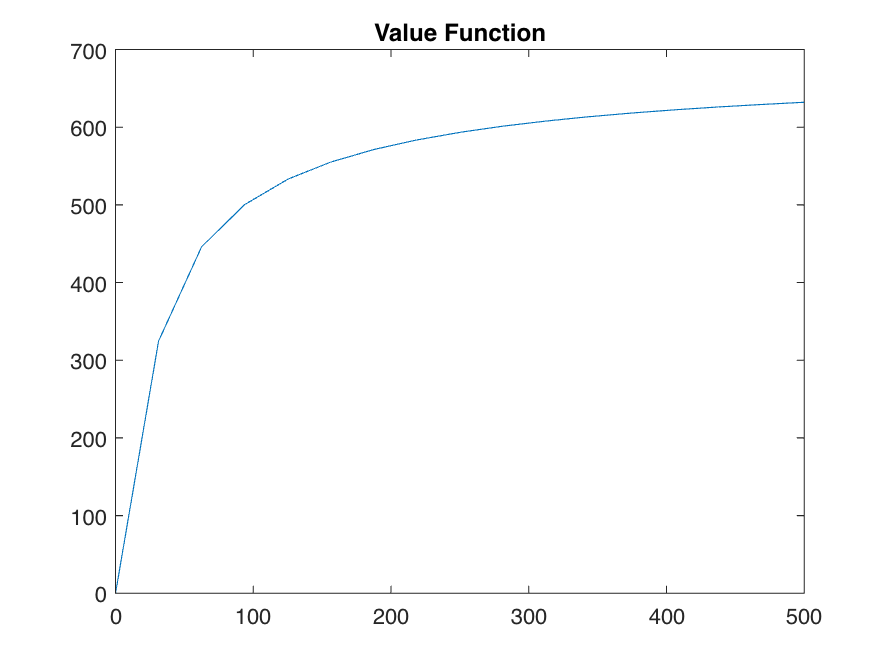


figure(1)
plot(m,V)
title('Value Function')

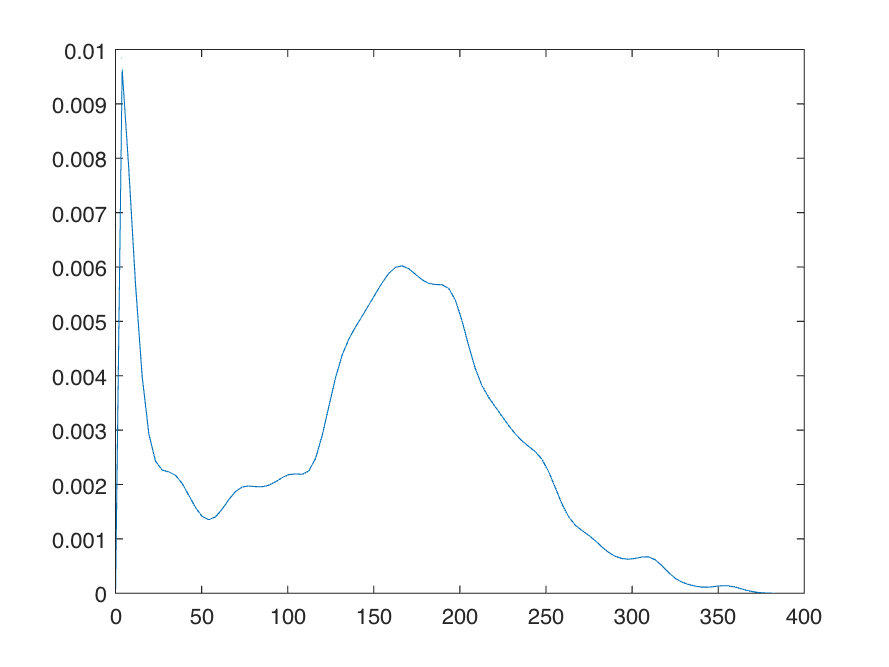


for i=1:N
    if Distribution(1,i)==0;
        Distribution(1,i)=0.001;
    end
end

[f,xi] = ksdensity(Distribution,'Support','positive','BoundaryCorrection','reflection','Bandwidth',std(Distribution)*0.1); 

figure(2)
plot(xi,f)

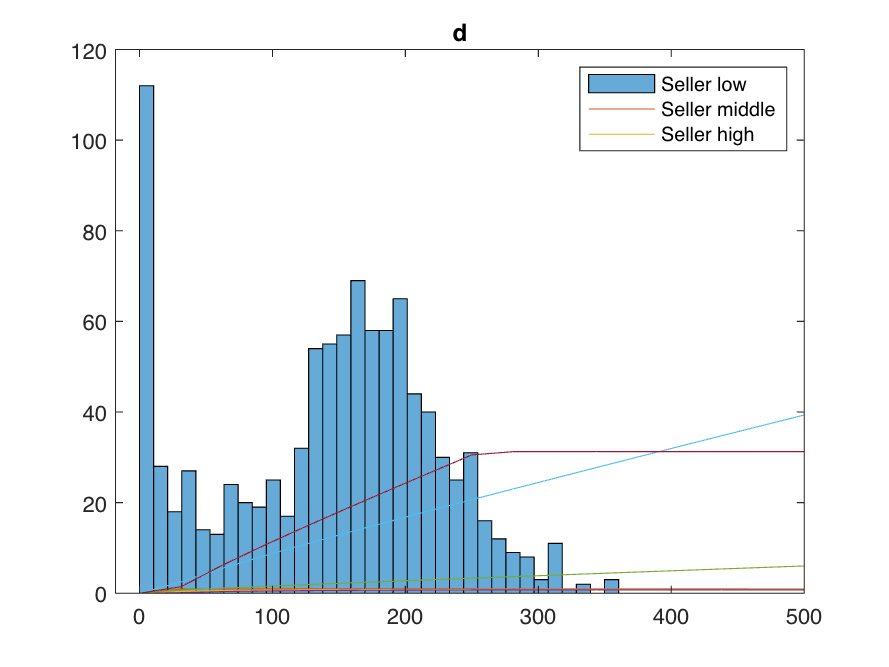



figure(3)
histogram(Distribution,grids*2)
 title('Distribution of Money holdings')

figure(4)
hold on
plot(m,q(:,1))
plot(m,q(:,round(grids/2)))
plot(m,q(:,grids-1))
legend('Seller low', 'Seller middle', 'Seller high')
hold off
title('q')


figure(5)
hold on
plot(m,d(:,1))
plot(m,d(:,round(grids/2)))
plot(m,d(:,grids-1))
legend('Seller low', 'Seller middle', 'Seller high')
hold off
title('d')

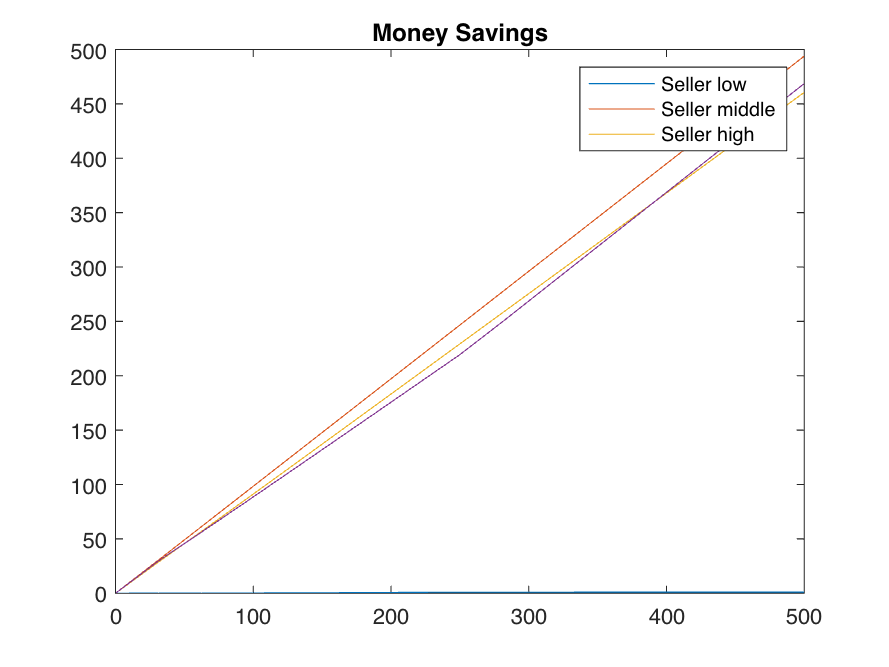


figure (6)
plot(m,cdf)
title('cdf')

m_savings_1=m'-d(:,1);
m_savings_2=m'-d(:,round(grids/2));
m_savings_3=m'-d(:,grids-1);
figure(7)
hold on
plot(m',m_savings_1)
plot(m',m_savings_2)
plot(m',m_savings_3)
legend('Seller low', 'Seller middle', 'Seller high')
hold off
title('Money Savings')


if cdf(grids)==1
    disp('cdf adds up to one')
else 
    disp('cdf does not add up to one')
    cdf(grids)
end

cdf adds up to one


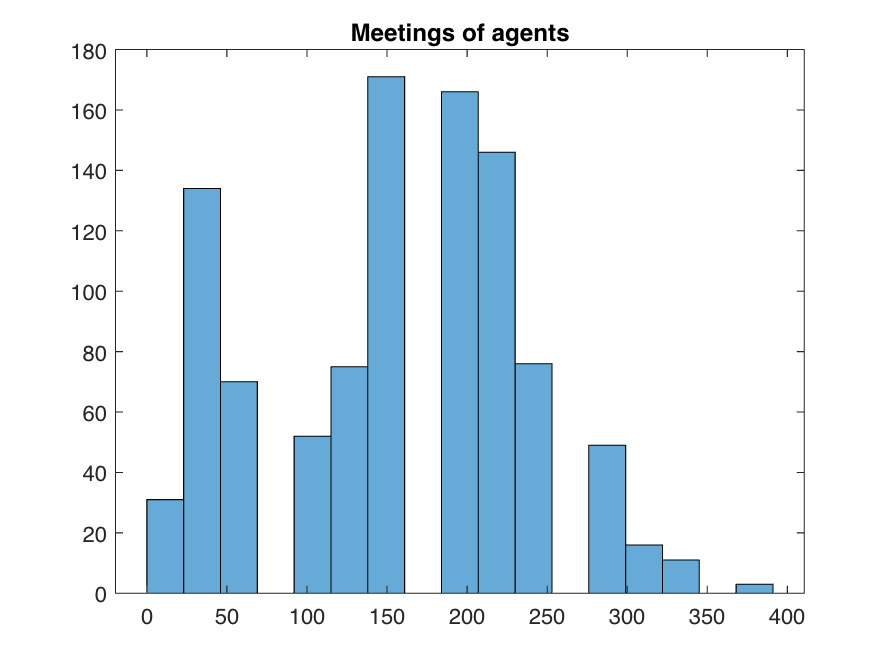

for i=1:N
Meeting(1,i)=m(1,Meeting(1,i));
end

figure (8)
histogram(Meeting,grids)
title('Meetings of agents')


lamdba

lamdba = 1×17
    0.0340    0.1220    0.0560    0.0590    0.0720    0.1560    0.1840    0.1480    0.0980    0.0390    0.0200    0.0090    0.0030         0         0         0         0



for i=1:grids
V_plot(1,i)=interp1(m,V,m(1,i),'spline',"extrap")-interp1(m,V,m(1,1),'spline',"extrap");
end



index=[1:iterations]

index = 1×10
     1     2     3     4     5     6     7     8     9    10


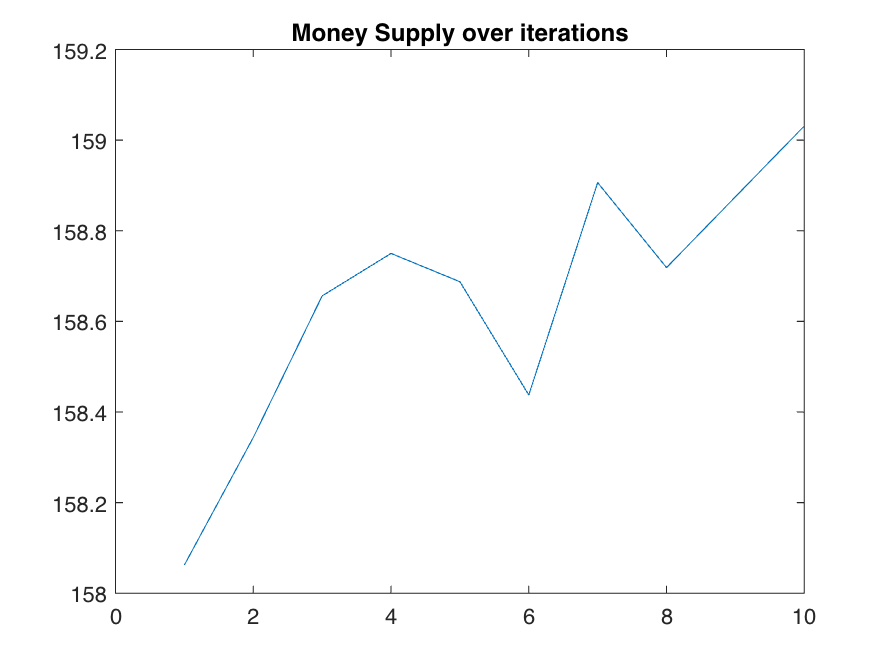

figure(9)
plot(index, M_track_1)
title('Money Supply over iterations')


average_q=sum(sum((lamdba'*lamdba)*q'))

average_q = 13.7882

mean(d./q)

ans = 1×17
    3.3104    5.1398    8.4362   11.2544   13.9188   16.4817   18.9891   21.4547   23.8864   26.2924   28.6784   31.0492   33.4090   35.7624   38.1116   32.6345         0
